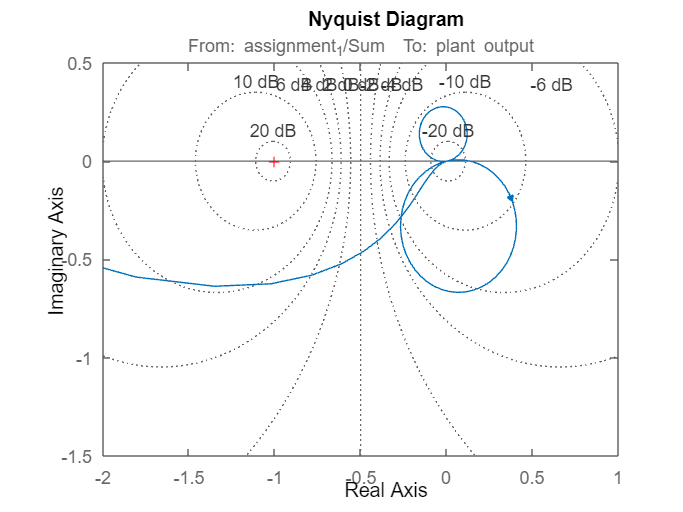


%System Parameters
m_lens = 2e-4; %mass of the lens, kg
m_rcoil = 5e-4; %mass of radial coil, kg
m_fcoil = 3e-4; % mass of the focal coil, kg

m2 = m_lens+m_rcoil+m_fcoil; %mass of the total system, m1, kg
m1 = 100e-3; %mass of the frame, m2, kg

f_dist = 25; %natural frequency of the system that connects frame to the fixed world, Hz
w_dist = 2*pi*f_dist;
f_sys = 40; %natural frequency of the system that connects frame to the system, Hz
w_sys = 2*pi*f_sys;

%calculating stiffness between a)world and frame, and b)frame and system
k1 = m1*(w_dist^2); %stiffness between world and the frame
k2 = m2*(w_sys^2); %stiffness between frame and system 

%damping and stiffness parameters of the system
z1 = 0.1;
c1 = 2*z1*sqrt(k1*m1);
z2 = 0.05;
c2 = 2*z2*sqrt(k2*m2);

z_fcoil = 0.005;
k_fcoil = 0.2e6; % stiffness in N/m
c_fcoil = 2*z_fcoil*sqrt(k_fcoil*m_fcoil); %is this correct? double check

z_lens = 0.005;
k_lens = 1e6; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); %is this correct? double check

%Rule of Thumb PID controller
Kp = k1;
f_bw = 800;

%calculating Td = 1/wd for derivative control
f_d = f_bw/3;
w_d = 2*pi*f_d;
T_d = 1/w_d;

%Calculating w_i
f_i = f_bw/10;
w_i = 2*pi*f_i;
T_i = 1/w_i;

%Q2
k_fcoil = 0.2e15; % stiffness in N/m
c_fcoil = 2*z_fcoil*sqrt(k_fcoil*m_fcoil); %is this correct? double check
k_lens = 1e15; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); %is this correct? double check

%Q3 This may be unneccessary. Just comment above?
k_fcoil = 0.2e6; % stiffness in N/m
c_fcoil = 2*z_fcoil*sqrt(k_fcoil*m_fcoil); %is this correct? double check
k_lens = 1e6; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); %is this correct? double check


%Q5
%Load the linearizer .mat file

Linearizer_3 = load("Assignment_3_linearizer.mat");

%Linsys 1 and 3 are both the same, just bode and nyquist.
%Linsys 4/6 and 5/7 for k = 150 and k= 100 for bode/nyquist.
%Linsys 8/9 is optimal mechanical s
Linsys1 = Linearizer_3.LinearAnalysisToolProject.Results(1).Data.Value;
%plot the Nyquist plot
figure;
h = nyquistplot(Linsys1);
setoptions(h, 'ShowFullContour', 'off');
xlim([-2 1])
ylim([-1.5 0.5])
grid on

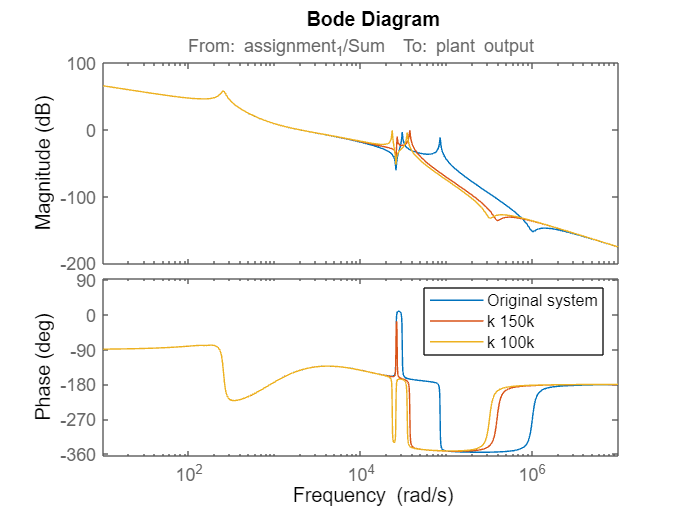


%Q6

%Define stiffness of 150k N/m
% k_lens = 150e3; % stiffness in N/m
% c_lens = 2*z_lens*sqrt(k_lens*m_lens); %is this correct? double check

% %Define stiffness of 100k N/m
% k_lens = 100e3; % stiffness in N/m
% c_lens = 2*z_lens*sqrt(k_lens*m_lens); %is this correct? double check

%Getting transfer functions from .mat file
Linsys_k150 = Linearizer_3.LinearAnalysisToolProject.Results(4).Data.Value;
Linsys_k100 = Linearizer_3.LinearAnalysisToolProject.Results(5).Data.Value;

%Plot Bode comparisons
figure;
bode(Linsys1,Linsys_k150,Linsys_k100)
legend('Original system','k 150k','k 100k')


%Plot Nyquist comparisons
nyquist(Linsys1,Linsys_k150,Linsys_k100)
legend('Original system','k 150k','k 100k')
setoptions(h, 'ShowFullContour', 'off');

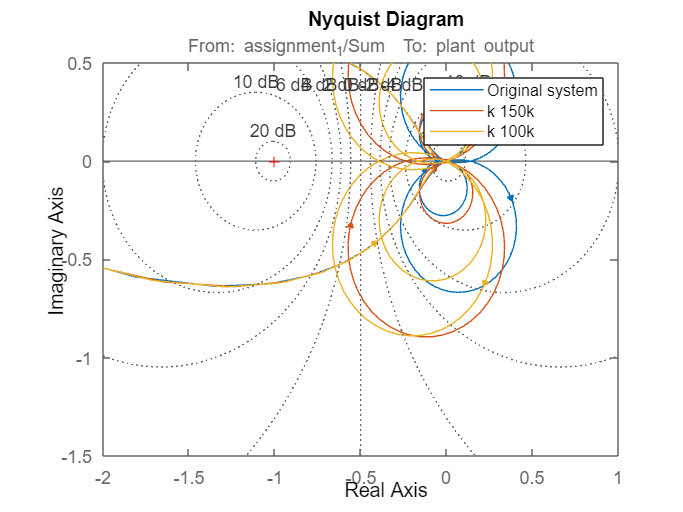

xlim([-2 1])
ylim([-1.5 0.5])
grid on

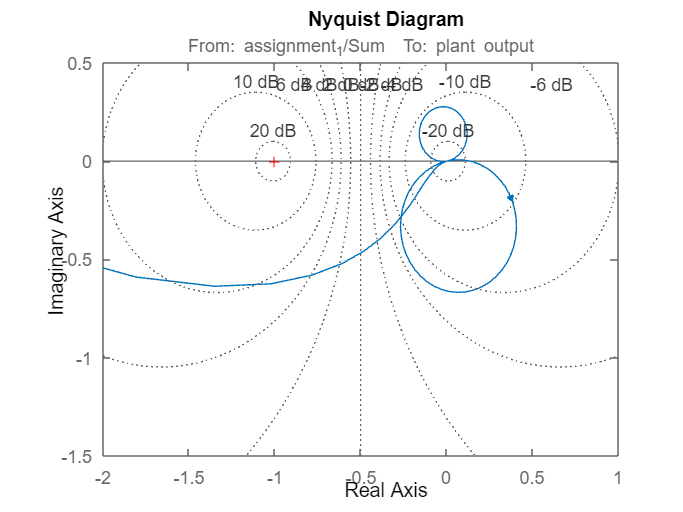


%Define optimal stiffness 
%Value found by getting close to zero phase change at the resonance
k_lens = 133.35e3; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); %is this correct? double check

%Getting transfer function for the optimized mechanical system 
Linsys_optimal = Linearizer_3.LinearAnalysisToolProject.Results(8).Data.Value;

%Plotting Nyquist 
nyquist(Linsys_optimal)
legend('Optimal mechanical system')
setoptions(h, 'ShowFullContour', 'off');

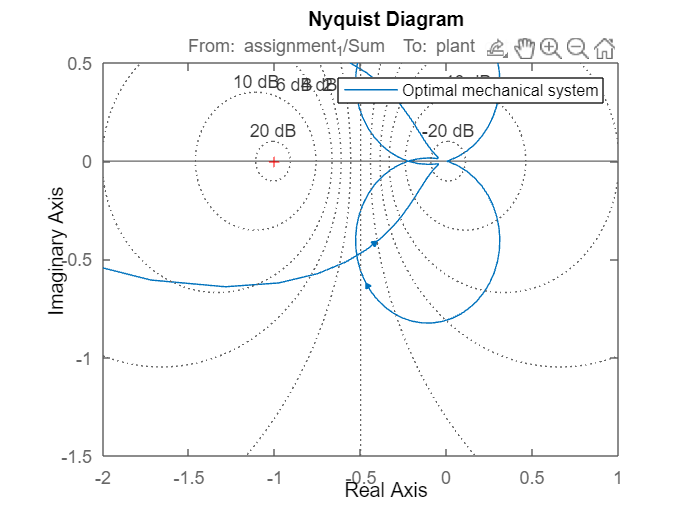

xlim([-2 1])
ylim([-1.5 0.5])
grid on

%Q7
%Add low pass filter?
%LPF, starting with f_bw*10 then try to shift up and down.
f_lpf = f_bw*10; 
